b) Plot the function f(x) and its Fourier sine series and Haar wavelet approximations on the same plot. Repeat this process for g(x) in a new figure.

c) Which expansion does a better job? How many terms are needed to capture the behavior? How are you classifying ‘better’?

d) Compare and contrast the different expansion methods Fourier sine series and Haar wavelets. Which one is most appropriate when, etc? Give strengths and weaknesses of both.

In order compare the behavior of two method I will control the term that these method will have.

Since haar only has 8 term, Fourier will also get 8 term.

i)f(x)

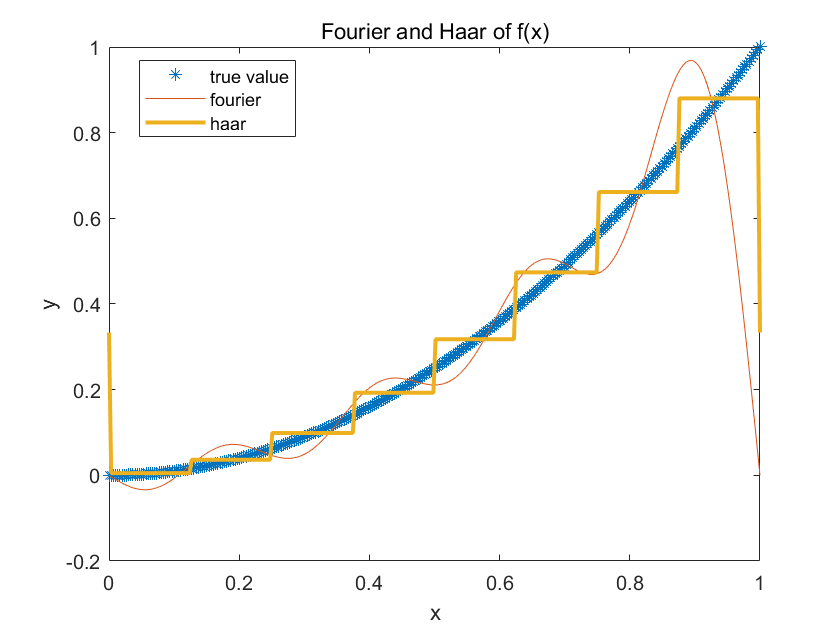

clear
n=8;%set n
num=300;
x=linspace(0,1,num);%define x
c1=[1/3 -1/4 -sqrt(2)/32 -3*sqrt(2)/32 -1/128 -3/128 -5/128 -7/128];
%define c0 to c7
[yreal1]=f(x); %f(x)
[yfourier1]=fs1(x,n);%fourier value
%haar value
[yhaar1]=c1(1)*h0(x)+c1(2)*h1(x)+c1(3)*h2(x)+c1(4)*h3(x)+c1(5)*h4(x)+c1(6)*h5(x)+c1(7)*h6(x)+c1(8)*h7(x);

plot(x,yreal1,'*')
hold on
plot(x,yfourier1)
plot(x,yhaar1,'LineWidth',2)
xlabel('x')
ylabel('y')
title('Fourier and Haar of f(x)')
legend('true value','fourier','haar','Location','best')
hold off

From the plot: Fourier seems done better job than Haar,

In order to classify them, I will compute the variance of the difference of the expansion value and real value

if the var(difference) is high which mean the method works not good.

%variance of the difference of the expansion value and real value
VarHaar=var(yhaar1-yreal1)

VarHaar = 0.0036

VarFouier=var(yfourier1-yreal1)

VarFouier = 0.0247

from the result above, haar has less variance than fourier, due to the Gibbs phonomenon, Fouirer will have bad behavior at the edge of the function.

And if we only take some part of the function

p=0.97;%take 97% of the data
VarHaar97=var(yhaar1(1:floor(num*p))-yreal1(1:floor(num*p)))

VarHaar97 = 0.0019

VarFouier97=var(yfourier1(1:floor(num*p))-yreal1(1:floor(num*p)))

VarFouier97 = 0.0069

From the result above, with the 97% of the data, fourier will do better than Haar.

ii)g(x)

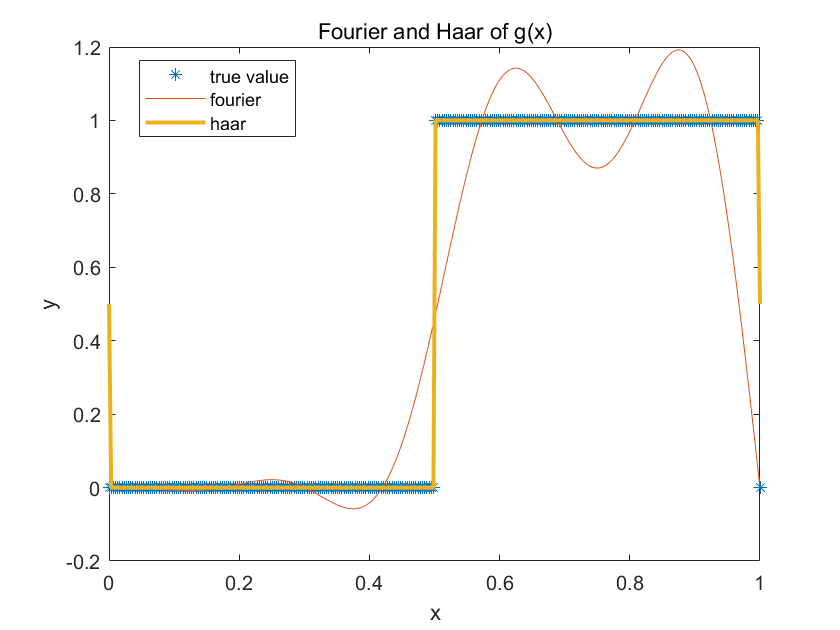

c2=[1/2 -1/2 0 0 0 0 0 0];
[yreal2]=g(x);
[yfourier2]=fs2(x,n);
[yhaar2]=c2(1)*h0(x)+c2(2)*h1(x)+c2(3)*h2(x)+c2(4)*h3(x)+c2(5)*h4(x)+c2(6)*h5(x)+c2(7)*h6(x)+c2(8)*h7(x);

plot(x,yreal2,'*')
hold on
plot(x,yfourier2)
plot(x,yhaar2,'LineWidth',2)
xlabel('x')
ylabel('y')
title('Fourier and Haar of g(x)')
legend('true value','fourier','haar','Location','best')
hold off

From the plot above, haar are almost coincide with the real function.

Fourier works badly since the term are less.

%variance of the difference of the expansion value and real value
VarHaar2=var(yhaar2-yreal2)

VarHaar2 = 0.0017

VarFouier2=var(yfourier2-yreal2)

VarFouier2 = 0.0352

With the result of variance

variance the haar method are more less than the fourier

So if we increase the term fourier

nt=10

nt = 10

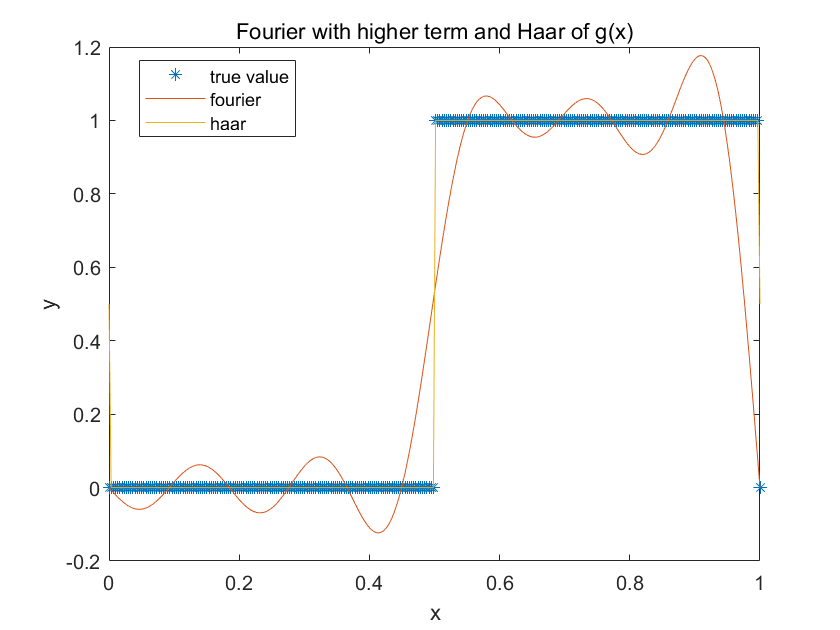

[yfouriert]=fs2(x,nt);

plot(x,yreal2,'*')
hold on
plot(x,yfouriert)
plot(x,yhaar2)
xlabel('x')
ylabel('y')
title('Fourier with higher term and Haar of g(x)')
legend('true value','fourier','haar','Location','best')
hold off

from the plot the fourier seem works better than before

VarHaar2new=var(yhaar2-yreal2)

VarHaar2new = 0.0017

VarFouier50term=var(yfouriert-yreal2)

VarFouier50term = 0.0248

Then from the result of the variance, we could see the even fourier has 50 term, it still has less accurate with Haar.

c)

From the case above

Fourier will works better with the curves function, but behave bad when a function has lots of jump point since the Gibbs phonomenon.

Haar will works better with the striate line function especially with the function has lots of jump point, but behave badly when deal with the curves function

function [y]=fs1(x,n)
%fourier transfrom of f(x)
    y=0;
    for i=1:n
        y=y+2*(2*pi*i*sin(i*pi)+(2-i^2*pi^2)*cos(i*pi)-2)/(i^3*pi^3)*sin(i*pi*x);    
    end
    
end

function [y]=fs2(x,n)
%fourier transfrom of g(x)
    y=0;
    for i=1:n
        y=y+2*(cos(i*pi/2)-cos(i*pi))/(i*pi)*sin(i*pi*x);    
    end
end

function [y]=f(x)
%f(x)
    y=x.^2;
end

function [y]=g(x)
%g(x)
    l=length(x);
    y=zeros(1,l);
    for i=1:l
        if 0<x(i) && x(i)<1/2
            y(i)=0;
        elseif 1/2<x(i) && x(i)<1
            y(i)=1;
        end    
    end
end

function [y]=h0(x)
%h0 function of haar
    y=0*x+1;
end

function [y]=h1(x)
%h1 function of haar
    l=length(x);
    y=zeros(1,l);
    for i=1:l
        if 0<x(i) && x(i)<1/2
            y(i)=1;
        elseif 1/2<x(i) && x(i)<1
            y(i)=-1;
        end    
    end
end

function [y]=h2(x)
%h2 function of haar
    l=length(x);
    y=zeros(1,l);
    for i=1:l
        if 0<x(i) && x(i)<1/4
            y(i)=sqrt(2);
        elseif 1/4<x(i) && x(i)<1/2
            y(i)=-sqrt(2);
        end    
    end
end

function [y]=h3(x)
%h3 function of haar
    l=length(x);
    y=zeros(1,l);
    for i=1:l
        if 1/2<x(i) && x(i)<3/4
            y(i)=sqrt(2);
        elseif 3/4<x(i) && x(i)<1
            y(i)=-sqrt(2);
        end    
    end
end

function [y]=h4(x)
%h4 function of haar
    l=length(x);
    y=zeros(1,l);
    for i=1:l
        if 0<x(i) && x(i)<1/8
            y(i)=2;
        elseif 1/8<x(i) && x(i)<1/4
            y(i)=-2;
        end    
    end
end

function [y]=h5(x)
%h5 function of haar
    l=length(x);
    y=zeros(1,l);
    for i=1:l
        if 1/4<x(i) && x(i)<3/8
            y(i)=2;
        elseif 3/8<x(i) && x(i)<1/2
            y(i)=-2;
        end    
    end
end

function [y]=h6(x)
%h6 function of haar
    l=length(x);
    y=zeros(1,l);
    for i=1:l
        if 1/2<x(i) && x(i)<5/8
            y(i)=2;
        elseif 5/8<x(i) && x(i)<3/4
            y(i)=-2;
        end    
    end
end

function [y]=h7(x)
%h7 function of haar
    l=length(x);
    y=zeros(1,l);
    for i=1:l
        if 3/4<x(i) && x(i)<7/8
            y(i)=2;
        elseif 7/8<x(i) && x(i)<1
            y(i)=-2;
        end    
    end
end

